clear all;

l_1 = 100/sqrt(3)-5-23;    %[mm]
l_2 = 50;                  %[mm]
l_3 = 100;                 %[mm]

alpha_1 = -20/180*pi;    
alpha_2 = -20/180*pi;
alpha_3 = -20/180*pi;
% alpha_1 = -30 * 5103.0/387283.0;
% alpha_2 = 0 * 5103.0/387283.0;  
% alpha_3 = -13 * 5103.0/387283.0;

c_1 = [0, -l_1 - cos(alpha_1)*l_2, sin(alpha_1)*l_2]';
c_2 = rotz(2*pi/3) * [0, -l_1 - cos(alpha_2)*l_2, sin(alpha_2)*l_2]';
c_3 = rotz(4*pi/3) * [0, -l_1 - cos(alpha_3)*l_2, sin(alpha_3)*l_2]';

syms t u v;

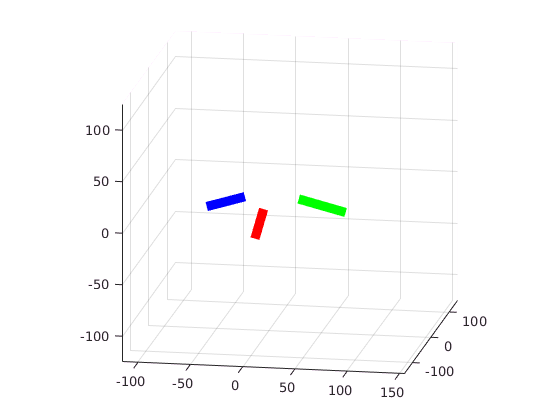

p = plot3([0 c_1(1)], [-l_1 c_1(2)], [0 c_1(3)], 'r', 'LineWidth', 7);
grid on
axis equal
hold on
xlim([-115 155]);
ylim([-145 145]);
zlim([-125 125]);
view([10 14]);
plot3([sin(2*pi/3)*l_1 c_2(1)], [cos(2*pi/3)*(-l_1) c_2(2)], [0 c_2(3)],  'g', 'LineWidth', 7);
plot3([sin(4*pi/3)*l_1 c_3(1)], [cos(4*pi/3)*(-l_1) c_3(2)], [0 c_3(3)],  'b', 'LineWidth', 7);

% sphere = [sin(u)*cos(v)*l_3, cos(u)*cos(v)*l_3, sin(v)*l_3]';
% fsurf(sphere(1)+c_1(1), sphere(2)+c_1(2), sphere(3)+c_1(3), [0 2*pi 0 2*pi], 'EdgeColor','r', 'LineStyle',':', 'facecolor','r', 'facealpha', 0.05, 'MeshDensity',15);
% fsurf(sphere(1)+c_2(1), sphere(2)+c_2(2), sphere(3)+c_2(3), [0 2*pi 0 2*pi], 'EdgeColor','g', 'LineStyle',':', 'facecolor','g', 'facealpha', 0.05, 'MeshDensity',15);
% fsurf(sphere(1)+c_3(1), sphere(2)+c_3(2), sphere(3)+c_3(3), [0 2*pi 0 2*pi], 'EdgeColor','b', 'LineStyle',':', 'facecolor','b', 'facealpha', 0.05, 'MeshDensity',15);

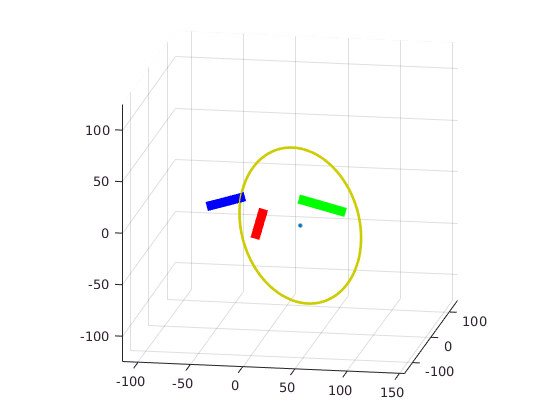


vec_dist_c1_c2 = c_2 - c_1;
dist_c1_c2 = norm(vec_dist_c1_c2);
center_intersection_sphere1_sphere2 = c_1 + vec_dist_c1_c2/2;
radius_intersection_sphere1_sphere2 = sqrt(l_3^2 - (dist_c1_c2/2)^2);
% plot3(center_intersection_sphere1_sphere2(1), center_intersection_sphere1_sphere2(2), center_intersection_sphere1_sphere2(3), '.', 'MarkerSize', 10);
rot_intersection_s1_s2 = vrrotvec2mat(vrrotvec([0 1 0]', vec_dist_c1_c2));
intersection_circle = rot_intersection_s1_s2 * [cos(t)*radius_intersection_sphere1_sphere2 0*t*radius_intersection_sphere1_sphere2 sin(t)*radius_intersection_sphere1_sphere2]' + double(center_intersection_sphere1_sphere2);
% fplot3(intersection_circle(1),intersection_circle(2),intersection_circle(3), 'Color', [0.8 0.8 0], 'LineWidth', 2);

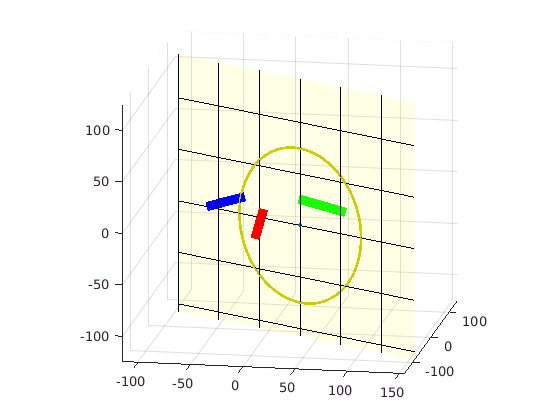

pos_vec_plane_intersection_s1_s2 = center_intersection_sphere1_sphere2;
normal_vec_plane = vec_dist_c1_c2/dist_c1_c2;
plane_x = [-150:50:150]';
plane_x = repmat(plane_x,1, size(plane_x,1));
plane_y = repmat([-150:50:150], size(plane_x,1),1);
plane_z = zeros(size(plane_x,1),size(plane_x,2));
rot_plane = vrrotvec2mat(vrrotvec([0 0 1]', normal_vec_plane));
plane = repmat(0, [3 size(plane_x,1) size(plane_x,2)]);
vec_plane_x = rot_plane * [1 0 0]';
%plot3([0 vec_plane_x(1)*100], [0 vec_plane_x(2)*100], [0 vec_plane_x(3)*100], 'k');
vec_plane_xy = cross(normal_vec_plane, [0 0 1]');
%plot3([0 vec_plane_xy(1)*100], [0 vec_plane_xy(2)*100], [0 vec_plane_xy(3)*100], 'k');
angle_plane = acos(dot(vec_plane_x, vec_plane_xy)/(norm(vec_plane_x)*norm(vec_plane_xy)));
rot_plane = vrrotvec2mat([normal_vec_plane' -angle_plane]) * rot_plane;
plane(1,:,:) = plane_x;
plane(2,:,:) = plane_y;
plane(3,:,:) = plane_z;

for i = 1:size(plane,2)
    for j = 1:size(plane,3)
        plane(:,i,j) = (rot_plane * plane(:,i,j)) + pos_vec_plane_intersection_s1_s2;
    end
end

plane_x_rot = reshape(plane(1,:,:),size(plane,2),size(plane,3));
plane_y_rot = reshape(plane(2,:,:),size(plane,2),size(plane,3));
plane_z_rot = reshape(plane(3,:,:),size(plane,2),size(plane,3));

% surf(plane_x_rot, plane_y_rot, plane_z_rot, 'facecolor','y', 'facealpha',0.1);

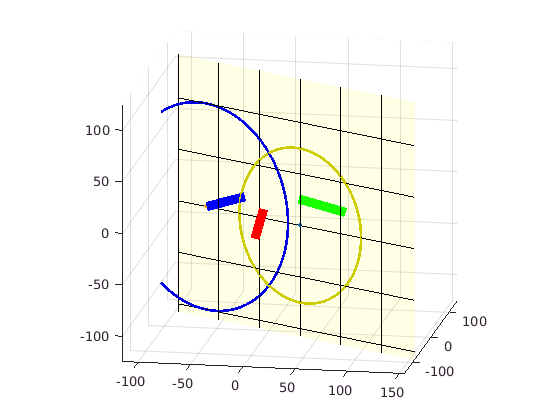

dist_plane_c3 = dot(normal_vec_plane, (c_3 - pos_vec_plane_intersection_s1_s2));
center_intersecton_plane_sphere3 = c_3 - dist_plane_c3 * normal_vec_plane;
radius_intersection_plane_sphere3 = sqrt(l_3^2 - dist_plane_c3^2);

plot3(center_intersecton_plane_sphere3(1), center_intersecton_plane_sphere3(2), center_intersecton_plane_sphere3(3), '.', 'MarkerSize', 10);
rot_intersection_plane_sphere3 = vrrotvec2mat(vrrotvec([0 1 0]', normal_vec_plane));
intersection_circle2 = rot_intersection_plane_sphere3 * [cos(t)*radius_intersection_plane_sphere3 0*t*radius_intersection_plane_sphere3 sin(t)*radius_intersection_plane_sphere3]' + center_intersecton_plane_sphere3;
% fplot3(intersection_circle2(1),intersection_circle2(2),intersection_circle2(3), 'Color', [0 0 0.9], 'LineWidth', 2);

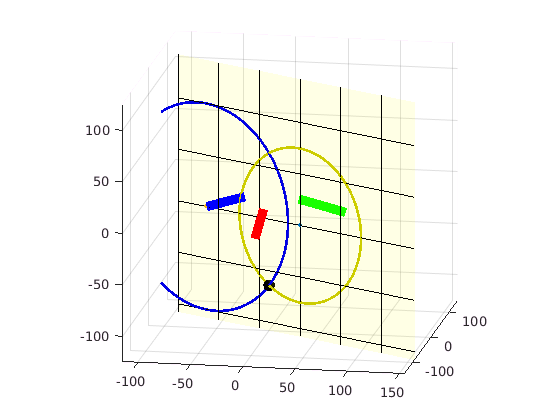

vec_dist_inter1_inter2 = center_intersecton_plane_sphere3 - center_intersection_sphere1_sphere2;
dist_inter1_inter2 = norm(vec_dist_inter1_inter2);
dist_center_inter1_to_radical_axis = (radius_intersection_sphere1_sphere2^2 - radius_intersection_plane_sphere3^2 + dist_inter1_inter2^2)/(2*dist_inter1_inter2);
dist_h = sqrt(radius_intersection_sphere1_sphere2^2 - dist_center_inter1_to_radical_axis^2);
vec_parallel_to_h = cross(vec_dist_inter1_inter2, normal_vec_plane);
vec_h_norm = vec_parallel_to_h/norm(vec_parallel_to_h);
vec_dist_inter1_radical_axis = vec_dist_inter1_inter2/norm(vec_dist_inter1_inter2)*dist_center_inter1_to_radical_axis;
vec_h = vec_h_norm*dist_h;
tool_center_point = center_intersection_sphere1_sphere2 + vec_dist_inter1_radical_axis + vec_h;
plot3(tool_center_point(1),tool_center_point(2),tool_center_point(3), 'k.', 'MarkerSize', 30);

l_check1 = norm(c_1 - tool_center_point)

l_check1 = 100

l_check2 = norm(c_2 - tool_center_point)

l_check2 = 100

l_check3 = norm(c_3 - tool_center_point)

l_check3 = 100.0000

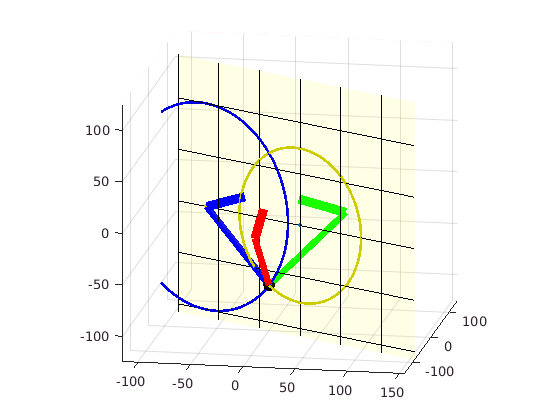

plot3([c_1(1) tool_center_point(1)], [c_1(2) tool_center_point(2)], [c_1(3) tool_center_point(3)], 'r', 'LineWidth', 5);
plot3([c_2(1) tool_center_point(1)], [c_2(2) tool_center_point(2)], [c_2(3) tool_center_point(3)], 'g', 'LineWidth', 5);
plot3([c_3(1) tool_center_point(1)], [c_3(2) tool_center_point(2)], [c_3(3) tool_center_point(3)], 'b', 'LineWidth', 5);

%hold off

vec_link1 = c_1 - [0 -l_1 0]'

vec_link1 =          0
  -46.9846
  -17.1010


vec_link2 = tool_center_point - c_1

vec_link2 =    -0.0000
   76.7197
  -64.1412


rotatet_z = rotz(0*pi/3) * rotx(-alpha_1) * [0 0 1]' *100

rotatet_z =          0
  -34.2020
   93.9693


% plot3([c_1(1) c_1(1)+rotatet_z(1)],[c_1(2) c_1(2)+rotatet_z(2)],[c_1(3) c_1(3)+rotatet_z(3)])
vec_orth_plane_arm1 = cross(vec_link1, rotatet_z) % and direction of rotation axis

vec_orth_plane_arm1 =    1.0e+03 *

   -5.0000
         0
         0


vec_orth_plane_arm1 = vec_orth_plane_arm1*100/norm(vec_orth_plane_arm1);
% plot3([c_1(1) c_1(1)+vec_orth_plane_arm1(1)],[c_1(2) c_1(2)+vec_orth_plane_arm1(2)],[c_1(3) c_1(3)+vec_orth_plane_arm1(3)])
vec_link2_proj = vec_link2 - vec_orth_plane_arm1*dot(vec_orth_plane_arm1,vec_link2)/norm(vec_orth_plane_arm1)^2

vec_link2_proj =          0
   76.7197
  -64.1412


hold off

betta_1_sign = sign(dot(vec_orth_plane_arm1, cross(vec_link1, vec_link2)))

betta_1_sign = -1

betta_1 = betta_1_sign * acos(dot(vec_link1, vec_link2_proj)/(norm(vec_link1) * norm(vec_link2_proj)))

betta_1 = -2.0962

betta_1_deg = betta_1/pi*180

betta_1_deg = -120.1028

cross(vec_orth_plane_arm1, vec_link2_proj)

ans =    1.0e+03 *

         0
   -6.4141
   -7.6720


cross(vec_link2_proj, vec_link2)

ans =    1.0e-12 *

         0
    0.4558
    0.5451


gamma_1_sign = sign(dot(cross(vec_orth_plane_arm1, vec_link2_proj), cross(vec_link2_proj, vec_link2)))

gamma_1_sign = -1

gamma_1 = gamma_1_sign * acos(dot(vec_link2, vec_link2_proj)/(norm(vec_link2) * norm(vec_link2_proj)))

gamma_1 = 0

gamma_1_deg = gamma_1/pi*180

gamma_1_deg = 0

link1_59 = [0.0308623 0.0178183 -0.0350717]';
link1_60 = [0.0304594 0.0175857 -0.0355382]';

pro_link3_59 = [-0.081142 -0.0468473 -0.0331675]';
pro_link3_60 = [-0.081256 -0.0469132 -0.0327874]';

cross(link1_59, pro_link3_59)

ans =    -0.0022
    0.0039
   -0.0000


cross(link1_60, pro_link3_60)

ans =    -0.0022
    0.0039
   -0.0000
